# **Econometrics 2 (Fall 2021)**

## **Jordan Holbrook**

## **Homework 5: Duration Models.**

Due Wednesday on Oct. 8th, 2021.

This code estimates, using maximum likelihood, the duration model where


$$f(t,\theta) = \theta e^{-\theta t} \text{ ,}$$


and $\theta_i = e^{\beta_0 + \beta_1 x_i}.$ You must modify the code to include incomplete spells.

## Set the parameters.

There are 50 simulations with 300 observations per simulation and calender time stops at $T =100$. Set $\beta_0 = 0.5 \text{ and } \beta_1 = 3.$

clear
clc

global x T t N

N = 300;                                            % Number of observations.
T = 100;                                              % Number of periods in calendar time.
beta0 = 0.5;                                        % Beta 0.
beta1 = 3;                                        % Beta 1.

sim = 50;                                          % Number of simulations.
results_mat = zeros(sim, 2);                                                % Results matrix.

## Maximum Likelihood Estimation.

In each simulation, generate the data, $X$, then draw the durations for each. To include incomplete spells, censor values of $t$ greater than $T$. Estimate the model using maximum likelihood and record the estimates.

x = ((1:N)'./N).*normrnd(0,1,N,1);
    
for s = 1:sim

    % Generate duration data from exponential distribution.
    
    theta = exp(beta0 + beta1*x);
    t = exprnd(1./theta,N,1);
    
    % ML estimation.
    
    b0 = [0 0.5];

    options = optimset('Display','off');
    [b_mle, ~, ~, ~, ~, hess] = fminunc('logl_dur_jh', b0, options);

    results_mat(s,1:size(results_mat,2)) = b_mle';
    vmat = inv(hess);

end

## Display the results of the last simulation.

The estimate and standard error (in parenthesis) of $\beta_0$ in the last simulation is:

fprintf(' %0.4f\n(%0.4f)\n',b_mle(1),sqrt(vmat(1,1)))

 0.8289
(0.0483)


The estimate and standard error (in parenthesis) of $\beta_1$ in the last simulation is:

fprintf(' %0.4f\n(%0.4f)\n',b_mle(2),sqrt(vmat(2,2)))

 3.5152
(0.2135)


## Empirical results.

The average and standard deviation (in parenthesis) of $\beta_0$ is:

fprintf(' %0.4f\n(%0.4f)\n', mean(results_mat(:,1)), std(results_mat(:,1)))

 0.7617
(0.1514)


The average and standard deviation (in parenthesis) of $\beta_1$ is:

fprintf(' %0.4f\n(%0.4f)\n', mean(results_mat(:,2)), std(results_mat(:,2)))

 3.2639
(0.4902)


## Plot the estimated coefficients from all simulations.

bins = 10;

Plot a histogram of $\beta_0$.

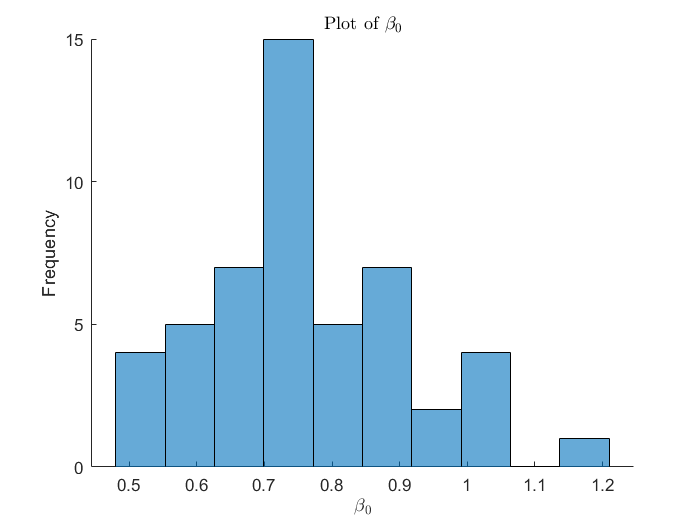

close all
figure(1)
hold on
histogram(results_mat(:,1),bins)
xlabel('$\beta_{0}$','interpreter','LaTex'); ylabel('Frequency')
title('Plot of $\beta_{0}$','interpreter','LaTex')
hold off

Plot a histogram of $\beta_1$.

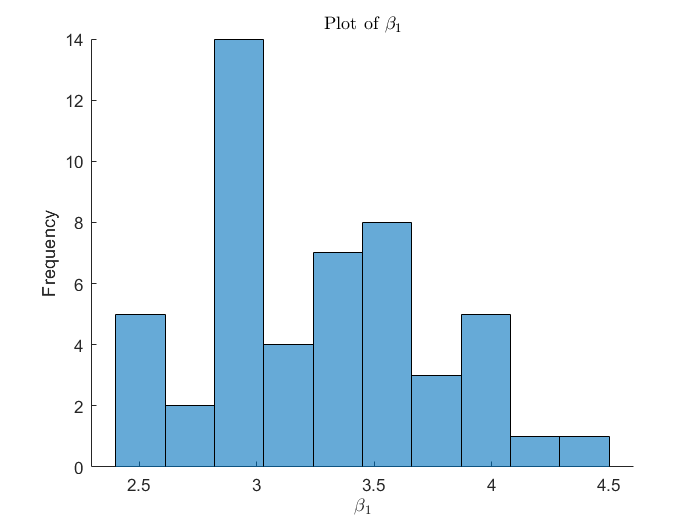

figure(2)
hold on
histogram(results_mat(:,2),bins)
xlabel('$\beta_{1}$','interpreter','LaTex'); ylabel('Frequency')
title('Plot of $\beta_{1}$','interpreter','LaTex')
hold off